# Homework 5

## ADSI Problem 4.2: Autocorrelation functions from plot

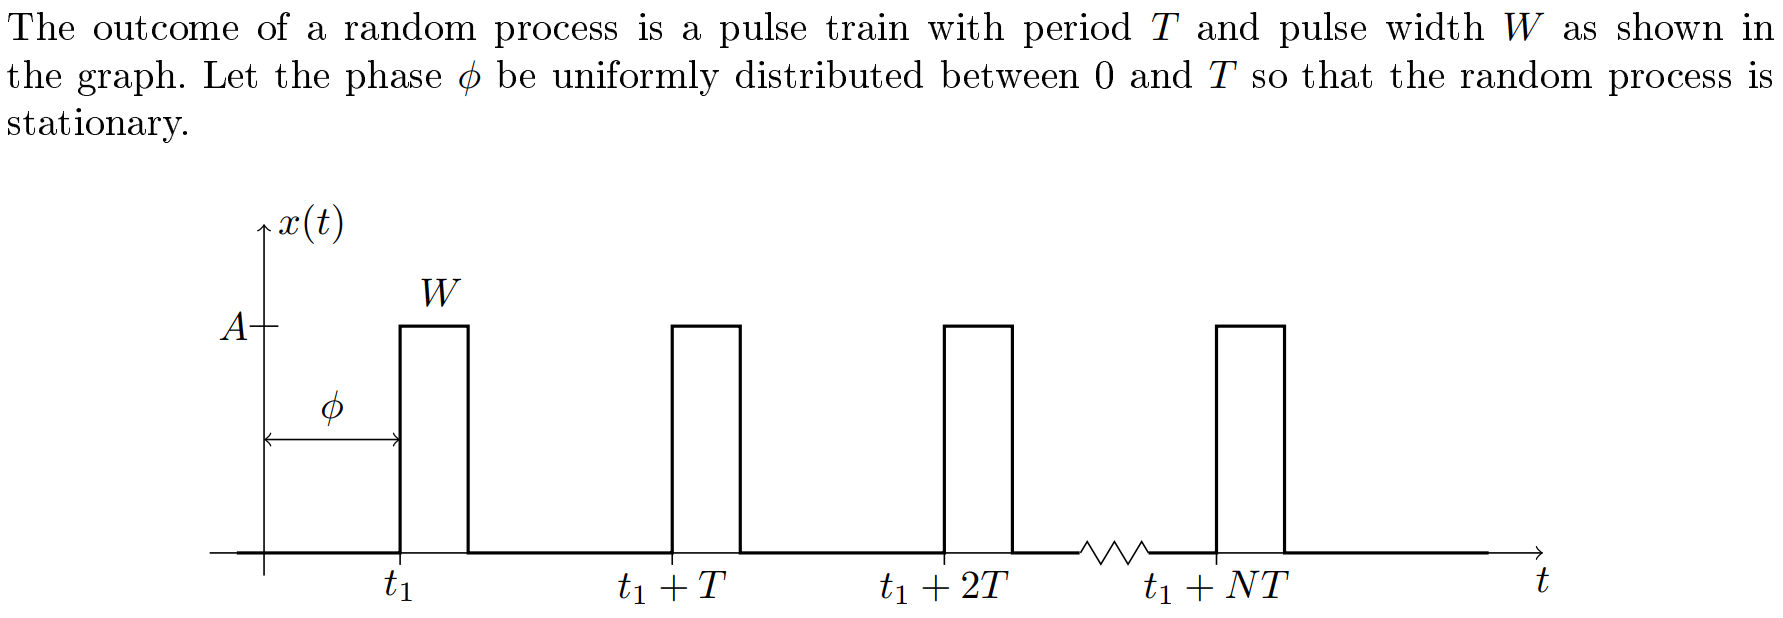

### 1) Sketch and explain what the autocorrelation looks like

### 2) Use computer simulations to verify the above result

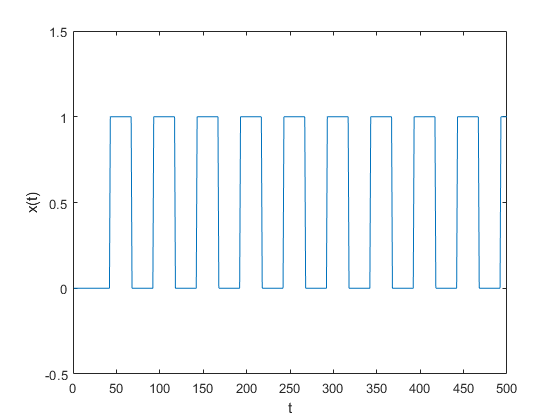

% Realization
A = 1;
W = 25;
T = 50;
N = 10;
phi = T*rand(1);

win = A*ones(1,W);
x = [zeros(1,round(phi)), repmat([1,zeros(1,T-1)],1,N)];
x = filter(win,1,x);
plot(x);
ylabel('x(t)');
xlabel('t');
ylim([-0.5, 1.5]);
xlim([0, T*N]);

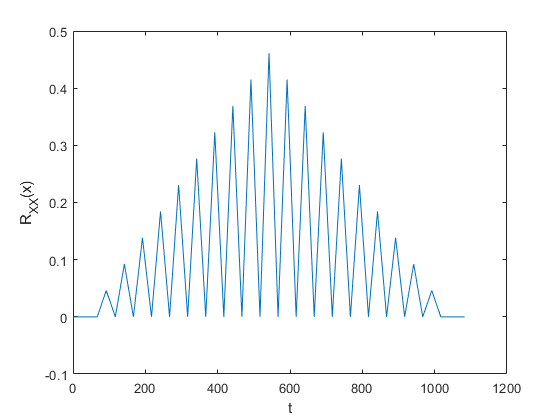

% Autocorrelation
Rxx = xcorr(x,'biased');
plot(Rxx)
ylabel('R_{XX}(x)')
xlabel('t')

## ADSI Problem 4.4: MA(q) processes

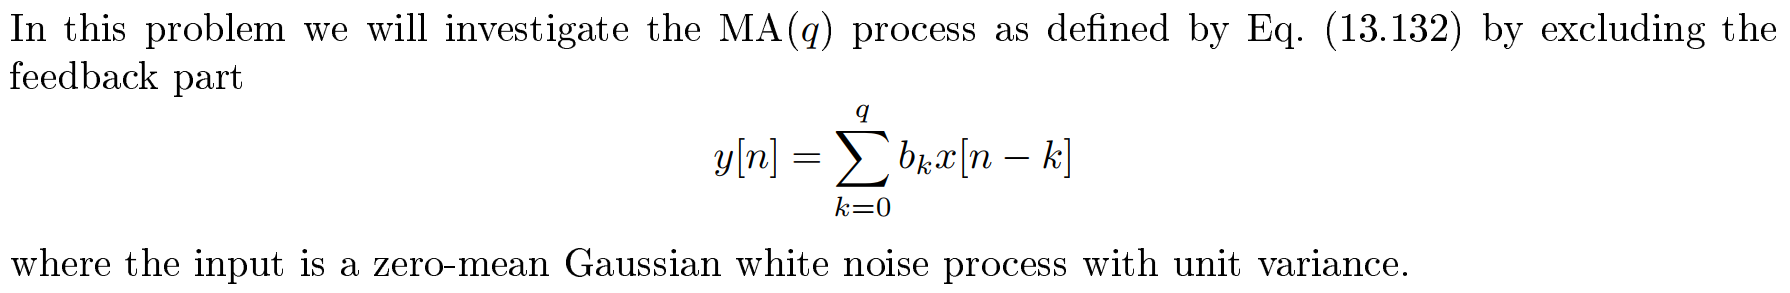

### 1) Write out the full expressions

The general $\mathrm{ARMA}\left(p,q\right)$is given by the difference equation:

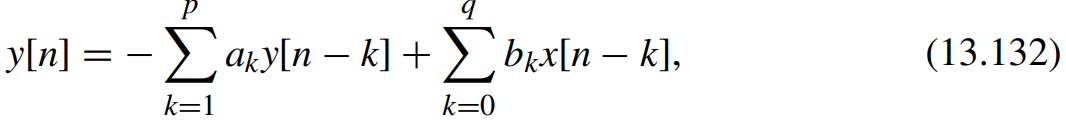

When the feedback part is excluded, all values of $a_k$ is set to zero, we are left with:


$$y\left\lbrack n\right\rbrack =\sum_{k=0}^q b_k \;x\left\lbrack n-k\right\rbrack$$


We can write out the full expressions for the difference processes as follows:


$$\mathrm{MA}\left(0\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack$$
 


$$\mathrm{MA}\left(1\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack$$



$$\mathrm{MA}\left(2\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack$$



$$\mathrm{MA}\left(3\right)\;\;\to \;\;y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack +b_3 \;x\left\lbrack n-3\right\rbrack$$


### 2) Calcute the autocorrelation for the MA processes

The autocorrelation function of a random process is defined as:

 
$$r_{\mathrm{yy}} \left(\ell \right)=E\left\lbrack y\left(n\right)\cdot y\left(n-\ell \right)\right\rbrack$$


To compute the autocorrelation for the $\mathrm{MA}\left(0\right)$, just plug its difference equation into this equation:

 
$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0 \;x\left(n\right)\cdot b_0 \;x\left(n-\ell \right)\right\rbrack$$


 
$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 E\left\lbrack x\left(n\right)\cdot x\left(n-\ell \right)\right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;r_{\mathrm{xx}} \left(\ell \right)$$
 

Since $r_{\mathrm{xx}} \left(\ell \right)=\sigma^2 \delta \left(l\right)=\delta \left(l\right)$. Why?


$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;\delta \left(l\right)$$
 

The autocorrelation for the $\textrm{MA}\left(1\right)$ process is:


$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack \left(b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack \right)\cdot \left(b_0 \;x\left\lbrack n-\ell \right\rbrack +b_1 \;x\left\lbrack n-\ell -1\right\rbrack \right)\right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +b_0 b_1 \;x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack +b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=E\left\lbrack b_0^2 \;x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack +b_0 b_1 \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)+b_1^2 x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;E\left\lbrack \left(x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack +x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right)\right\rbrack +b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$



$$r_{\textrm{yy}} \left(\ell \right)=b_0^2 \;E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack +b_0 b_1 \;\left(E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack +E\left\lbrack x\left\lbrack n-1\right\rbrack \;x\left\lbrack n-\ell \right\rbrack \right\rbrack \right)+b_1^2 \;E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack$$


Since

- 
$$E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack =r_{\mathrm{xx}} \left(\ell \right)$$


- 
$$E\left\lbrack x\left\lbrack n\right\rbrack x\left\lbrack n-\ell -1\right\rbrack \right\rbrack =r_{\textrm{xx}} \left(\ell -1\right)$$


- 
$$E\left\lbrack x\left\lbrack n-1\right\rbrack x\left\lbrack n-\ell \right\rbrack \right\rbrack =r_{\mathrm{xx}} \left(\ell +1\right)$$


### 3) Calculate power density spectra

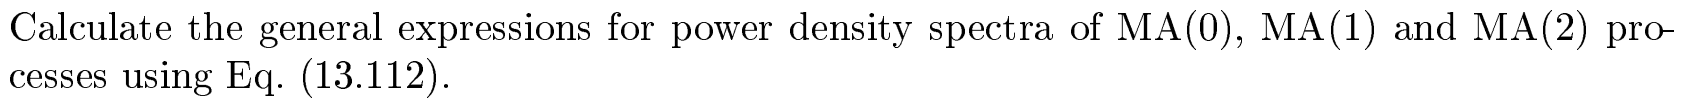

### 4) Plot the power density spectra

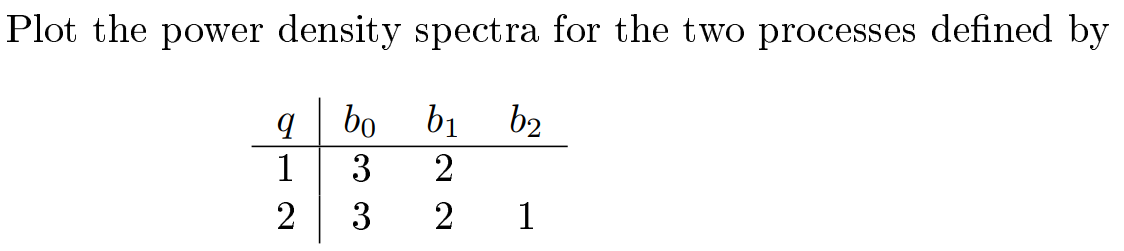

## ADSI Problem 4.5: MA processes and phase properties

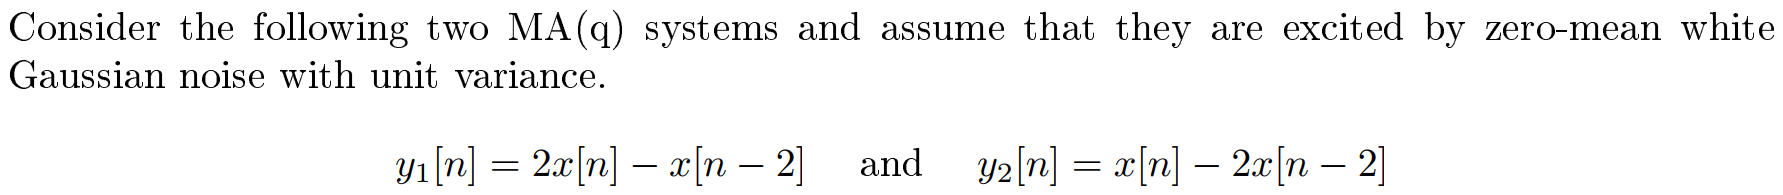

### 1) What is the order q of the processes

### 2) Compare the phase properties of the two systems

### 3) Calculate and plot the power density spectra of the two systems and comment on the result

## ADSI Problem 4.6: MA processes, output corrupted

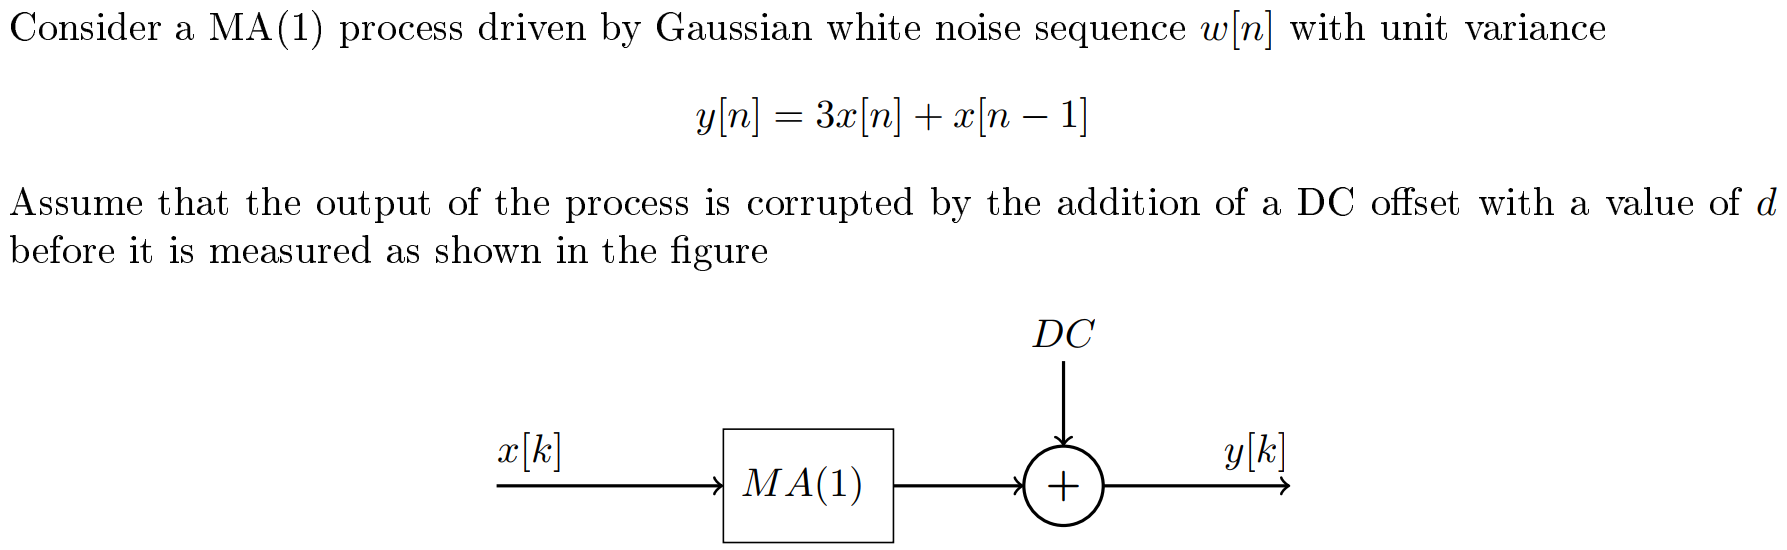

### 1) Calculate the autocorrelation of the corrupted signal

### 2) How is the power density spectrum of the *MA*(1) process affected by the DC-offset? 

## Exam 2012 Problem 4: Wiener filter for recovering corrupted signal

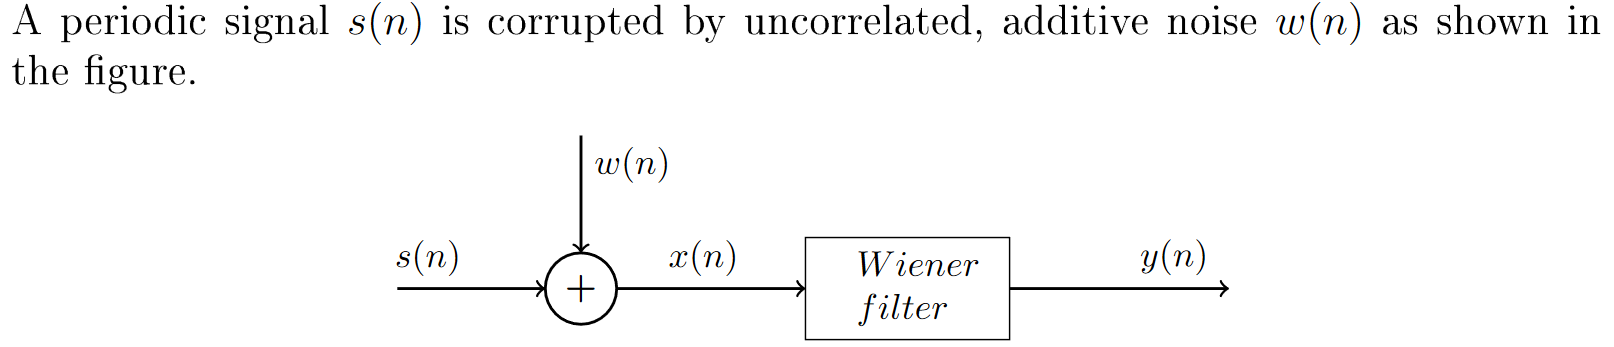

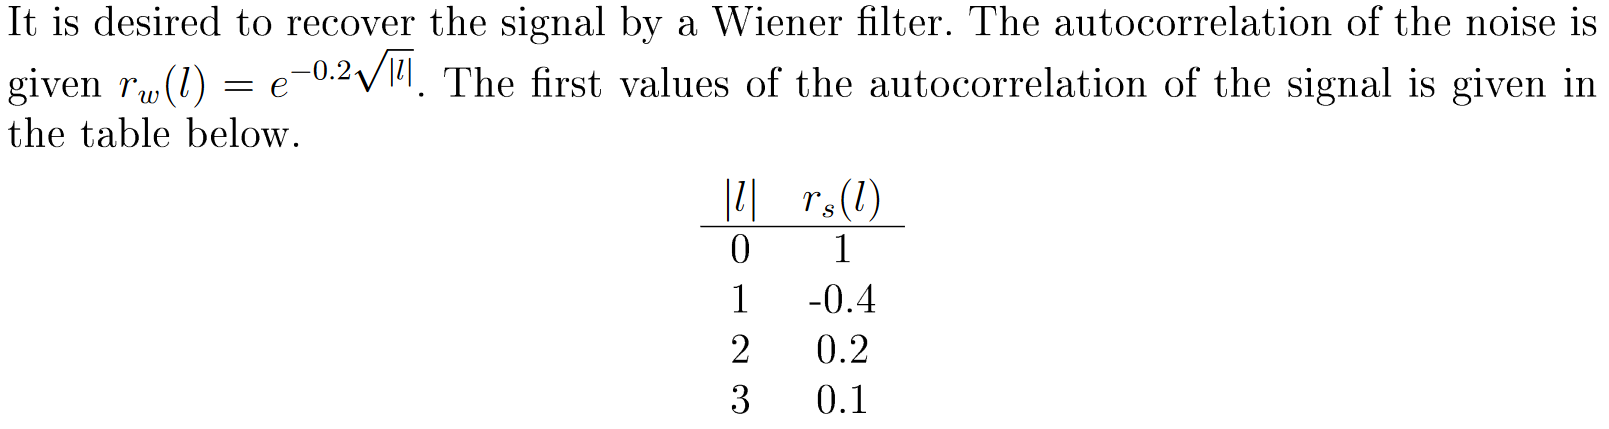

### 1) Design a 3 tap Wiener filter to recover s(n)

### 2) Calculate the minimum mean square error

### 3) Discuss another Wiener filter with 2x noise amplitude